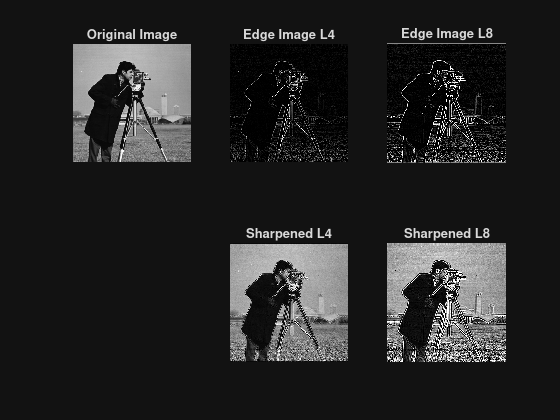

% laplacian - it enhance the edge detection and image sharpening

% s1: read the image
clc;
clear;
close all;
A = imread('cameraman.tif');   % you can change image name if needed
A = double(A);

% s2: define L4 mask and L8 mask
L4 = [0 -1 0;
     -1 4 -1;
      0 -1 0];

L8 = [-1 -1 -1;
      -1  8 -1;
      -1 -1 -1];

% s3: perform convolution (L4 and L8)
conv_L4 = conv2(A, L4, 'same');
conv_L8 = conv2(A, L8, 'same');

% s4: subtract and find sharpened image and edge image
sharpen_L4 = A - conv_L4;
sharpen_L8 = A - conv_L8;

edge_L4 = conv_L4;                                              
edge_L8 = conv_L8;

% display results
figure;

subplot(2,3,1), imshow(uint8(A)), title('Original Image');
subplot(2,3,2), imshow(uint8(edge_L4)), title('Edge Image L4');
subplot(2,3,3), imshow(uint8(edge_L8)), title('Edge Image L8');
subplot(2,3,5), imshow(uint8(sharpen_L4)), title('Sharpened L4');
subplot(2,3,6), imshow(uint8(sharpen_L8)), title('Sharpened L8');